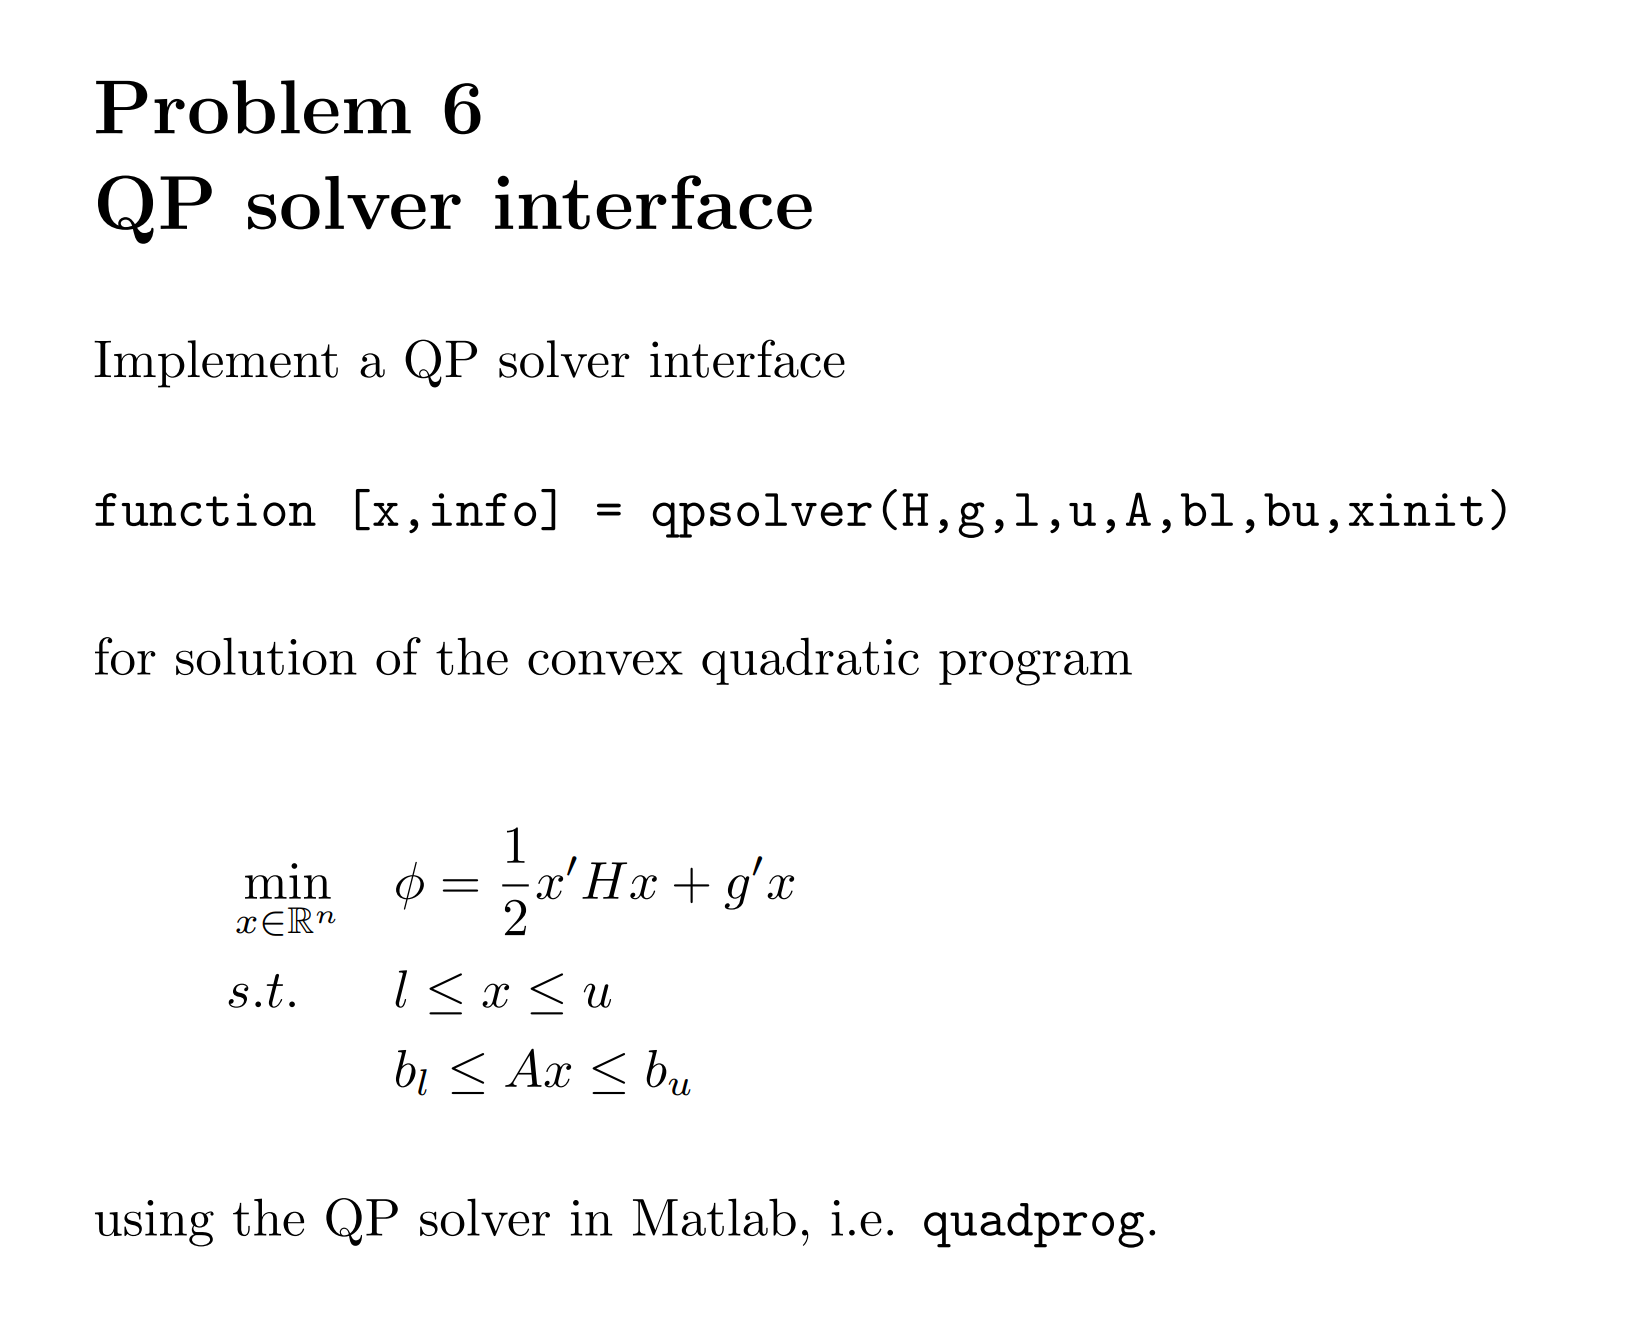

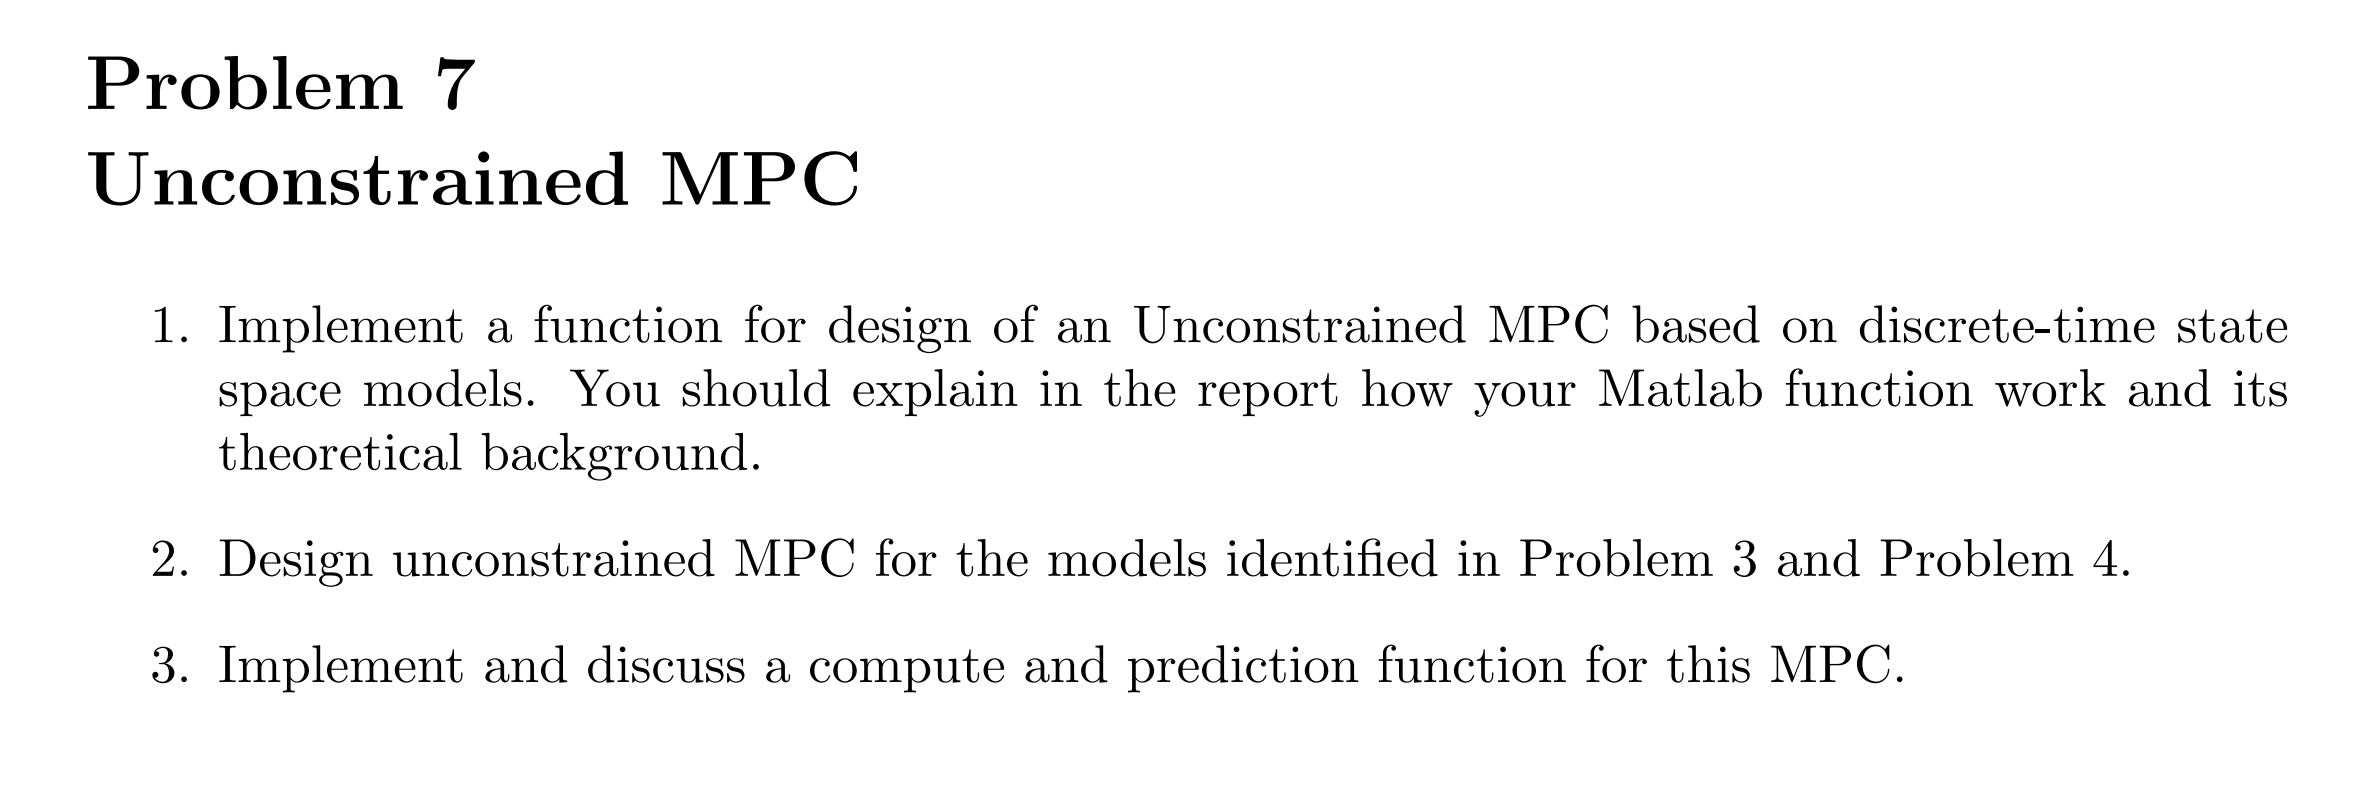

%测试线性系统下的mpc效果
t0 = 0.0; % [s] Initial time
t_final = 60*60; % [s] Final time
Ts = 4; % [s] Sample Time (4s for the step)
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 250;
F4 = 250;
%x0 = [m10; m20; m30; m40];
x0=xs;
% Process Noise
Q = [0.5^2 0;0 0.5^2];
Lq = chol(Q,'lower');
w = Lq*randn(2,N);
% Measurement Noise
R_low = eye(4);
Lr_low = chol(R_low,'lower');
v_low = Lr_low*randn(4,N);
R_mid = 10*eye(4);
Lr_mid = chol(R_mid,'lower');
v_mid = Lr_mid*randn(4,N);
R_high = 20*eye(4);
Lr_high = chol(R_high,'lower');
v_high = Lr_high*randn(4,N);

index_step=100;
%step 0.05
u_50_F1 = [repmat(F1,1,N); repmat(F2,1,N)];
u_50_F2 = [repmat(F1,1,N); repmat(F2,1,N)];
u_50_F1(1,index_step:end)=F1*(1+0.5);
u_50_F2(2,index_step:end)=F2*(1+0.5);
%d = [repmat(F3,1,N); repmat(F4,1,N)];
d = [repmat(50,1,N); repmat(50,1,N)];
%d(1,index_step:end)=100*(1+0.5);
%step 0.1
u_10_F1 = [repmat(F1,1,N); repmat(F2,1,N)];
u_10_F2 = [repmat(F1,1,N); repmat(F2,1,N)];
u_10_F1(1,index_step:end)=F1*(1+0.1);
u_10_F2(2,index_step:end)=F2*(1+0.1);
%step 0.25
u_25_F1 = [repmat(F1,1,N); repmat(F2,1,N)];
u_25_F2 = [repmat(F1,1,N); repmat(F2,1,N)];
u_25_F1(1,index_step:end)=F1*(1+0.25);
u_25_F2(2,index_step:end)=F2*(1+0.25);
%impulse 0.1
u_impluse_F1=[repmat(F1,1,N); repmat(F2,1,N)];
u_impluse_F2=[repmat(F1,1,N); repmat(F2,1,N)];
u_impluse_F1(1,index_step)=F1*(1+0.1);
u_impluse_F2(2,index_step)=F2*(1+0.1);

dw=d+w;
num_x=4;
num_u=2;
num_d=2;
num_y=4;
num_z=2;
num_eta=num_y;

N_pre=50;
u_min=0;
u_max=600;
z_min=0;
z_max=170;
u_delta_min=-5;
u_delta_max=5;
x = zeros(num_x,N);
y = zeros(num_y,N);
z = zeros(num_z,N);
u = zeros(num_u,N);
x_bar = zeros(num_x,N);
d_bar = zeros(num_d,N);

x0=zeros(4,1);
d0=zeros(2,1);
x(:,1) = x0;
x_bar(:,1) = x0;
d_bar(:,1) = d0;
xk=x_bar(:,1);
ref=160;
%使用输出约束MPC时需要重构ref
%rk=ref*ones(N_pre*num_z,1);%z1,z2 ref
rk=ref*ones(N_pre*num_y,1);%y1,y2,y3,y4
%使用观测disturbance的第一个值时，需要重构d
%dk=[repmat(d_bar(1,1),N_pre,1); repmat(d_bar(2,1),N_pre,1)];%d1,d2 ref
dk=d_bar(:,1);
uk=zeros(num_u,1);%d1,d2 ref
usk=repmat(us(1),N_pre*num_u,1);
Q_cof=90;
u_delta_cof=1000;%1000
eta_cof=1000;
Wu_cof=0.0001;
for k = 1:N-1
%sensor feedback
yk=Css*xk+Dss*uk+v_low(:,k); % Sensor function
yk_no_noise=Css*xk+Dss*uk;
zk=yk_no_noise(1:2,:); % Output function

%kalman observer
%static kalman
x_kf=[x_bar(:,k);d_bar(:,k)];
u_kf=uk;
x_kf=Ad_kf*x_kf+Bd_kf*u_kf+L_kf*(yk-(Cdy_kf*x_kf+Dss*u_kf));
xk = x_kf(1:num_x);
%dk = [repmat(x_kf(num_x+1),N_pre,1); repmat(x_kf(num_x+2),N_pre,1)];
dk=x_kf(num_x+1:num_x+2);

%dynamic kalman
% P = G_w*W_kf*G_w';
% x_kf=[x_bar(:,k);d_bar(:,k)];
% u_kf=u(:,k);
% y_bar=Cdy_kf*x_kf;
% e_bar=y(:,k)-y_bar;
% R=Cdy_kf*P*Cdy_kf'+R;
% K=P*Cdy_kf'*inv(R);
% x_kf=x_kf+K*e_bar;
% P=P-K*R*K';
% x_kf=Ad_kf*x_kf+Bd_kf*u_kf;
% P=Ad_kf*P*Ad_kf'+G_w*W_kf*G_w';
% %可以继续迭代求x
% %z_bar=Cz*x_kf;
% R=Cdy_kf*P*Cdy_kf';
% xk = x_kf(1:num_x);
% %dk = [repmat(X_bar(num_x+1),N_pre,1); repmat(X_bar(num_x+2),N_pre,1)];
% dk=x_kf(num_x+1:num_x+2);

%MPC controller assuming the disturbance of prediction time is all known
%uk=MPCcompute_linear(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre);
%uk=MPCcompute_linear_qp_analytical(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre,Q_cof,u_delta_cof);
%uk=MPCcompute_linear_qp_numerical(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre,Q_cof,u_delta_cof);
%uk=MPCcompute_linear_inputCons_qp_numerical(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,u_min,u_max,u_delta_min,u_delta_max,N_pre,Q_cof,u_delta_cof);
%uk=MPCcompute_linear_inputCons_outputSoftCons_qp_numerical(rk,xk,dk,uk,Ad,Bd,Bd_d,Css,u_min,u_max,u_delta_min,u_delta_max,z_min,z_max,N_pre,Q_cof,u_delta_cof,eta_cof);

%MPC controller only use the first disturbance
%uk=MPCcompute_linear_qp_analytical_kalman(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre,Q_cof,u_delta_cof);
%uk=MPCcompute_linear_qp_numerical_kalman(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre,Q_cof,u_delta_cof);
%uk=MPCcompute_linear_inputCons_qp_numerical_kalman(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,u_min,u_max,u_delta_min,u_delta_max,N_pre,Q_cof,u_delta_cof);
uk=MPCcompute_linear_inputCons_outputSoftCons_qp_numerical_kalman(rk,xk,dk,uk,Ad,Bd,Bd_d,Css,u_min,u_max,u_delta_min,u_delta_max,z_min,z_max,N_pre,Q_cof,u_delta_cof,eta_cof);

%uk=MPCcompute_linear_kalman_target(rk,xk,dk,uk,usk,Ad,Bd,Bd_d,Czss,N_pre,Q_cof,u_delta_cof,Wu_cof);
%uk=MPCcompute_linear_inputCons_kalman_target(rk,xk,dk,uk,usk,Ad,Bd,Bd_d,Czss,u_min,u_max,u_delta_min,u_delta_max,N_pre,Q_cof,u_delta_cof,Wu_cof);

%state update
xk=Ad*x(:,k)+Bd*uk+Bd_d*d(:,k)+Gw_d*w(:,k);


x(:,k+1)=xk;
y(:,k)=yk;
z(:,k)=zk;
u(:,k+1)=uk;
x_bar(:,k+1) = x_kf(1:num_x);
d_bar(:,k+1) = x_kf(num_x+1:end);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because the objective function

k=N;
yk=Css*x(:,k)+Dss*uk+v_low(:,k); % Sensor function
yk_no_noise=Css*xk+Dss*uk;
zk=yk_no_noise(1:2,:); % Output function
y(:,k)=yk;
z(:,k)=zk;

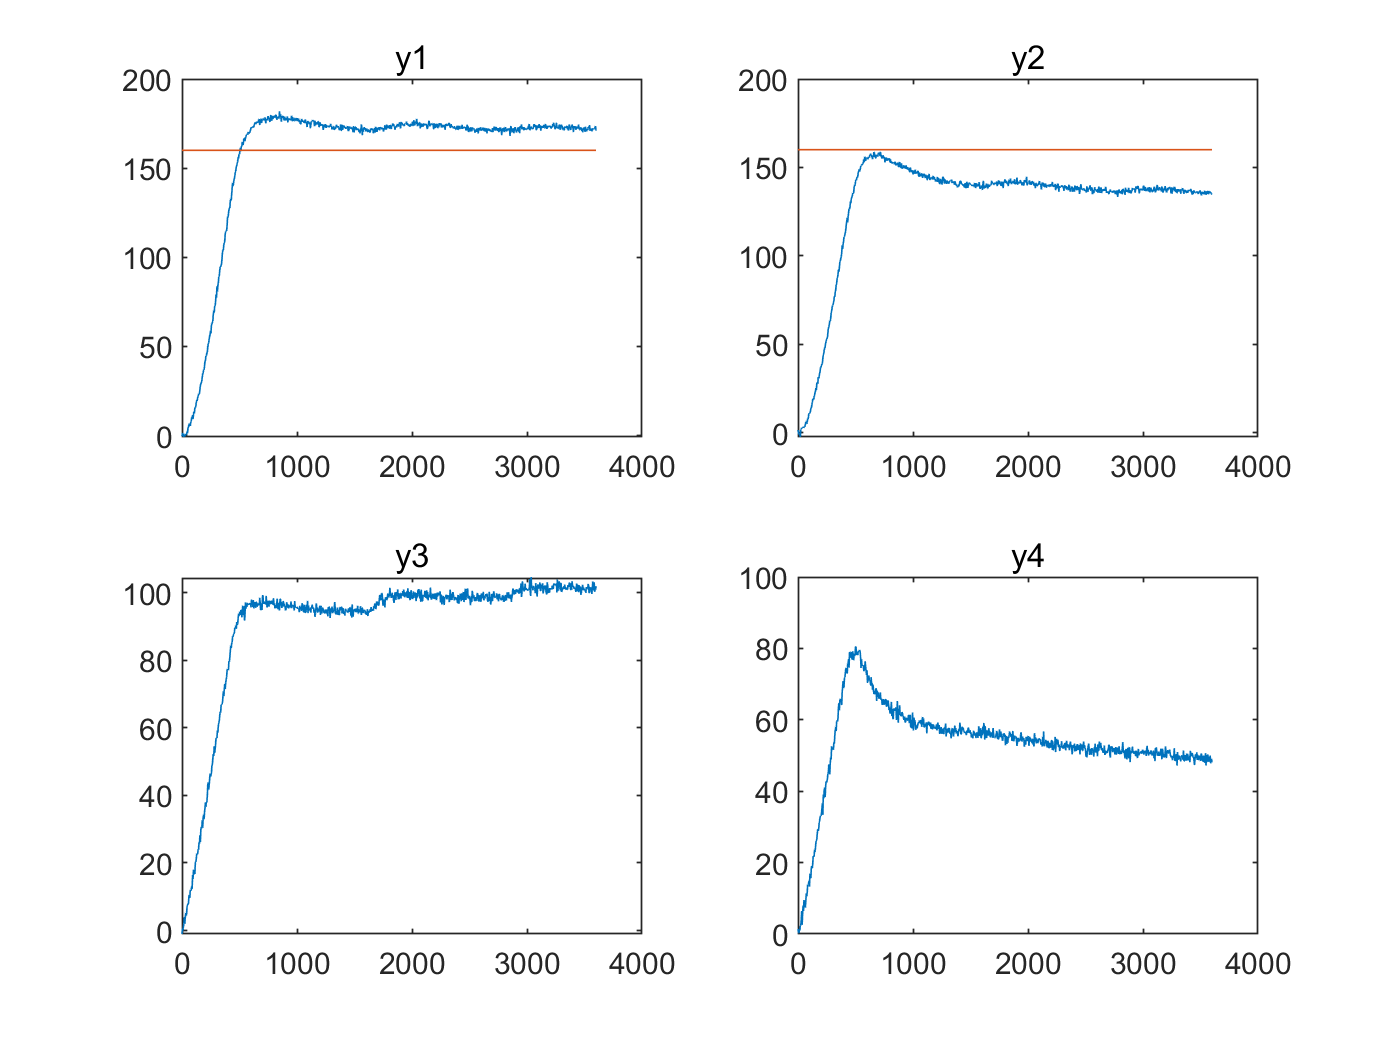

figure
subplot(2,2,1)
plot(t,y(1,:),t,(ref)*ones(size(t,1),1))
title('y1')
subplot(2,2,2)
plot(t,y(2,:),t,(ref)*ones(size(t,1),1))
title('y2')
subplot(2,2,3)
plot(t,y(3,:))
title('y3')
subplot(2,2,4)
plot(t,y(4,:))
title('y4')

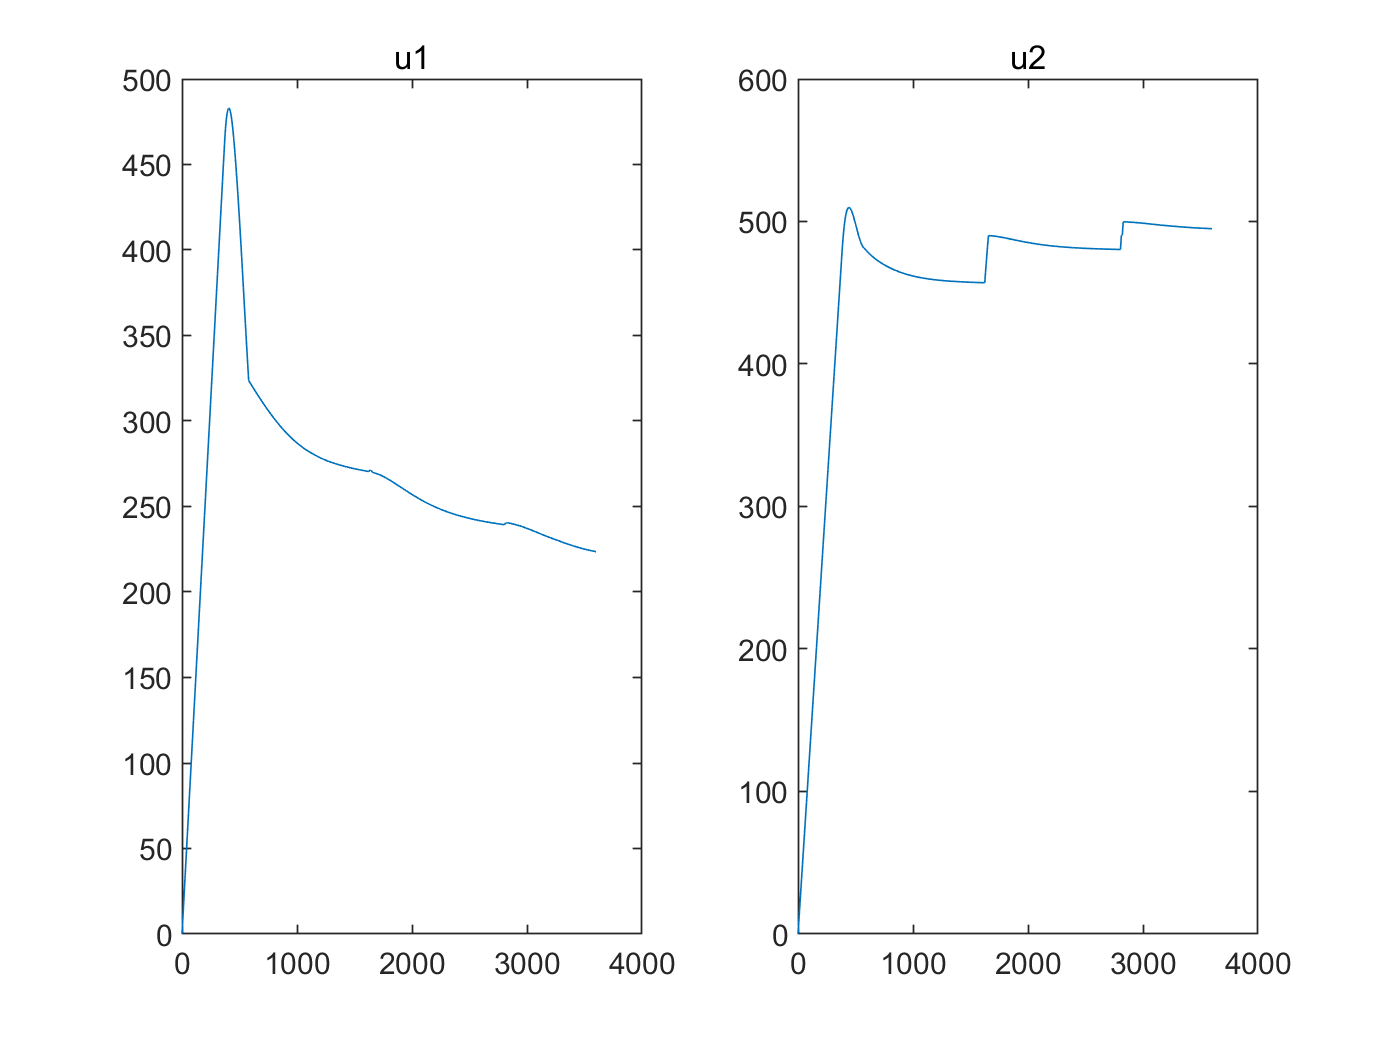

figure;
subplot(1,2,1)
plot(t,u(1,:))
title('u1')
subplot(1,2,2)
plot(t,u(2,:))
title('u2')

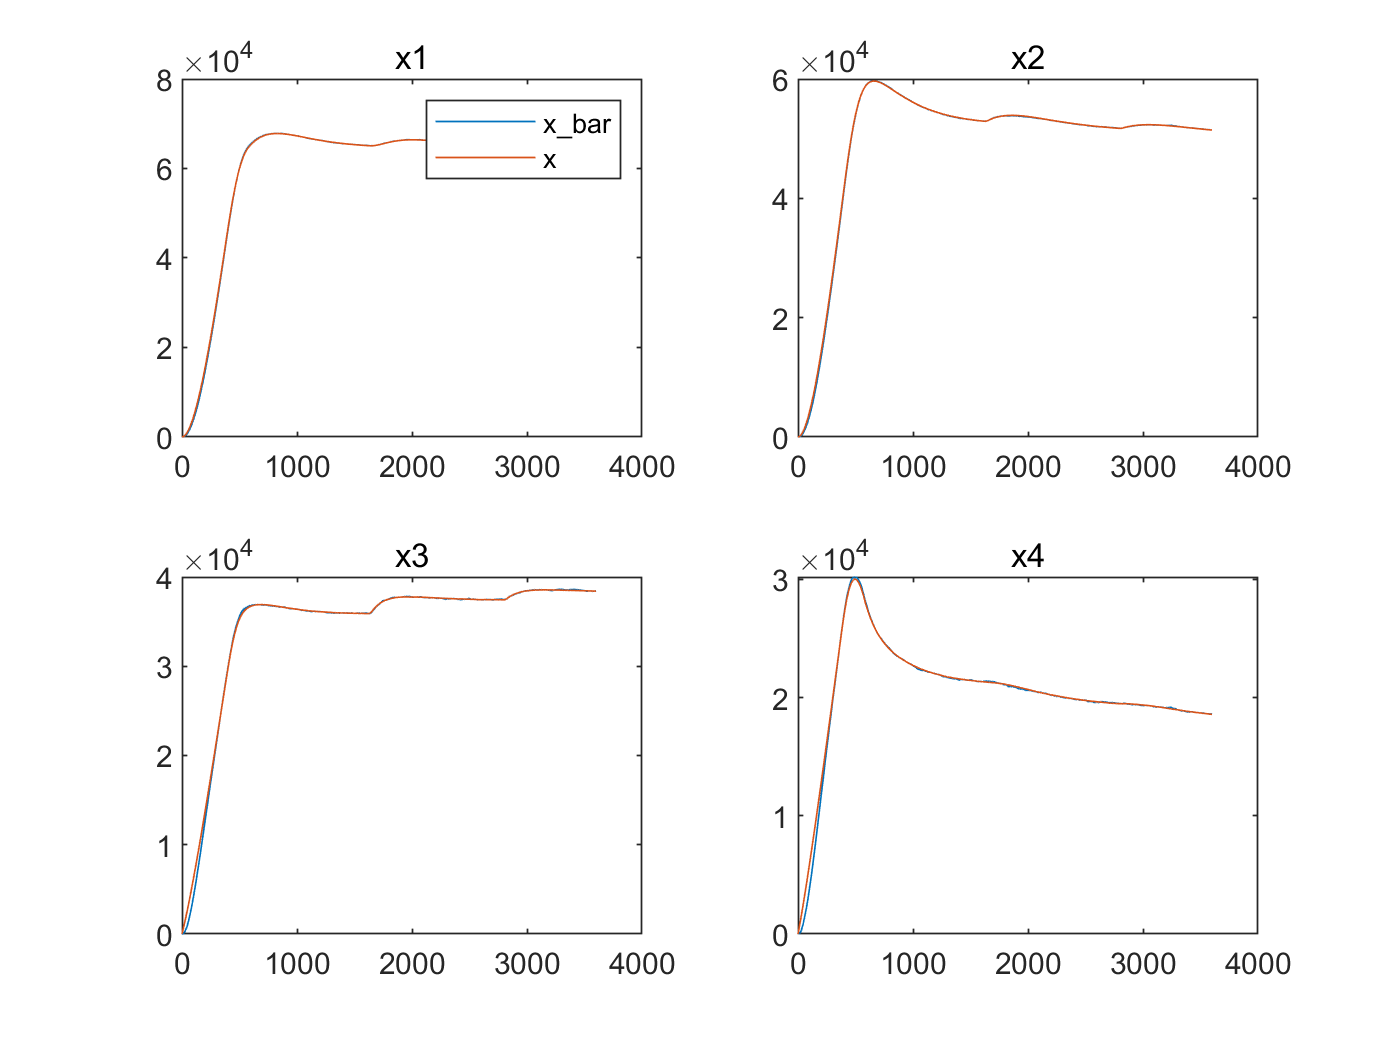

figure
subplot(2,2,1)
plot(t,x_bar(1,:),t,x(1,:))
title('x1')
legend('x\_bar','x')
subplot(2,2,2)
plot(t,x_bar(2,:),t,x(2,:))
title('x2')
subplot(2,2,3)
plot(t,x_bar(3,:),t,x(3,:))
title('x3')
subplot(2,2,4)
plot(t,x_bar(4,:),t,x(4,:))
title('x4')

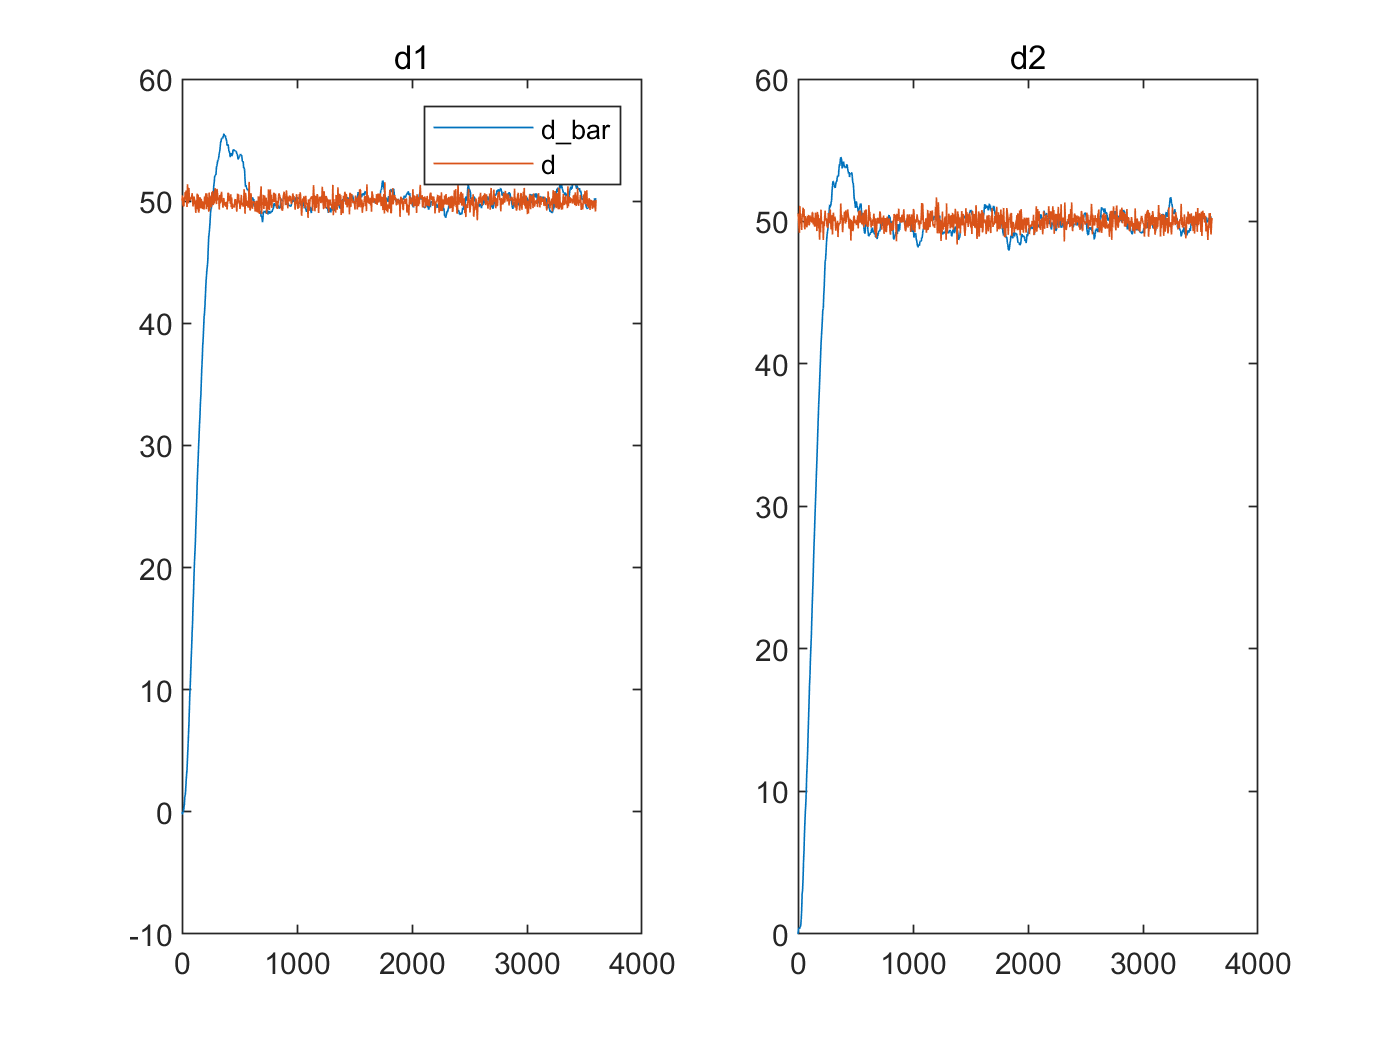

figure;
subplot(1,2,1)
plot(t,d_bar(1,:),t,dw(1,:));
title('d1')
legend('d\_bar','d')
subplot(1,2,2)
plot(t,d_bar(2,:),t,dw(2,:));
title('d2')

%测试非线性系统下的mpc效果
t0 = 0.0; % [s] Initial time
t_final = 60*60; % [s] Final time
Ts = 4; % [s] Sample Time (4s for the step)
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 250;
F4 = 250;
%x0 = [m10; m20; m30; m40];
x0=xs;
% Process Noise
Q = [2^2 0;0 4^2];
Lq = chol(Q,'lower');
w = Lq*randn(2,N);
% Measurement Noise
R_low = eye(4);
Lr_low = chol(R_low,'lower');
v_low = Lr_low*randn(4,N);
R_mid = 10*eye(4);
Lr_mid = chol(R_mid,'lower');
v_mid = Lr_mid*randn(4,N);
R_high = 20*eye(4);
Lr_high = chol(R_high,'lower');
v_high = Lr_high*randn(4,N);

index_step=100;
%step 0.05
u_50_F1 = [repmat(F1,1,N); repmat(F2,1,N)];
u_50_F2 = [repmat(F1,1,N); repmat(F2,1,N)];
u_50_F1(1,index_step:end)=F1*(1+0.5);
u_50_F2(2,index_step:end)=F2*(1+0.5);
%d = [repmat(F3,1,N); repmat(F4,1,N)];
d = [repmat(250,1,N); repmat(250,1,N)];
d(1,index_step:end)=250*(1+0.5);
%step 0.1
u_10_F1 = [repmat(F1,1,N); repmat(F2,1,N)];
u_10_F2 = [repmat(F1,1,N); repmat(F2,1,N)];
u_10_F1(1,index_step:end)=F1*(1+0.1);
u_10_F2(2,index_step:end)=F2*(1+0.1);
%step 0.25
u_25_F1 = [repmat(F1,1,N); repmat(F2,1,N)];
u_25_F2 = [repmat(F1,1,N); repmat(F2,1,N)];
u_25_F1(1,index_step:end)=F1*(1+0.25);
u_25_F2(2,index_step:end)=F2*(1+0.25);
%impulse 0.1
u_impluse_F1=[repmat(F1,1,N); repmat(F2,1,N)];
u_impluse_F2=[repmat(F1,1,N); repmat(F2,1,N)];
u_impluse_F1(1,index_step)=F1*(1+0.1);
u_impluse_F2(2,index_step)=F2*(1+0.1);

dw=d+w;
num_x=4;
num_u=2;
num_d=2;
num_y=4;
num_z=2;
num_eta=num_y;

N_pre=50;
u_min=0;
u_max=900;
z_min=0;
z_max=170;
u_delta_min=-5;
u_delta_max=5;
x = zeros(num_x,N);
y = zeros(num_y,N);
z = zeros(num_z,N);
u = zeros(num_u,N);
x_bar = zeros(num_x,N);
d_bar = zeros(num_d,N);

%x0=zeros(4,1);
x0=xs;
d0=zeros(2,1);
x(:,1) = x0;
x_bar(:,1) = x0;
d_bar(:,1) = d0;
xk=x_bar(:,1);
ref=160;
%rk=ref*ones(N_pre*num_z,1);%z1,z2 ref
rk=ref*ones(N_pre*num_y,1);%y1,y2,y3,y4
%dk=[repmat(d_bar(1,1),N_pre,1); repmat(d_bar(2,1),N_pre,1)];%d1,d2 ref
dk=d_bar(:,1);
uk=zeros(num_u,1);%d1,d2 ref
usk=[repmat(us(1),N_pre*num_u,1); zeros(N_pre*num_eta,1)];
Q_cof=80;
u_delta_cof=1;
eta_cof=1000;
Wu_cof=0.0001;
eta_cof1=500;%zmin
eta_cof2=10000;%zmax
for k = 1:N-1
%sensor feedback
yk = FourTankSystemSensorNoise(x(:,k),p,v_low(:,k));% Sensor function
zk = FourTankSystemOutput(x(:,k),p); % Output function

%kalman observer
%static observer
x_kf=[x_bar(:,k);d_bar(:,k)];
u_kf=uk;
x_kf=Ad_kf*x_kf+Bd_kf*u_kf+L_kf*(yk-(Cdy_kf*x_kf+Dss*u_kf));
xk = x_kf(1:num_x);
%dk = [repmat(X_bar(num_x+1),N_pre,1); repmat(X_bar(num_x+2),N_pre,1)];
dk=x_kf(num_x+1:num_x+2);

%dynamic kalman
% P = G_w*W_kf*G_w';
% x_kf=[x_bar(:,k);d_bar(:,k)];
% u_kf=u(:,k);
% y_bar=Cdy_kf*x_kf;
% e_bar=y(:,k)-y_bar;
% R=Cdy_kf*P*Cdy_kf'+R;
% K=P*Cdy_kf'*inv(R);
% x_kf=x_kf+K*e_bar;
% P=P-K*R*K';
% x_kf=Ad_kf*x_kf+Bd_kf*u_kf;
% P=Ad_kf*P*Ad_kf'+G_w*W_kf*G_w';
% %可以继续迭代求x
% %z_bar=Cz*x_kf;
% R=Cdy_kf*P*Cdy_kf';
% xk = x_kf(1:num_x);
% %dk = [repmat(X_bar(num_x+1),N_pre,1); repmat(X_bar(num_x+2),N_pre,1)];
% dk=x_kf(num_x+1:num_x+2);


%MPC controller
%uk=MPCcompute_linear(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre);
%uk=MPCcompute_linear_qp_analytical(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre,Q_cof,u_delta_cof);
%uk=MPCcompute_linear_qp_numerical(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre);
%uk=MPCcompute_linear_inputCons_qp_numerical(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,u_min,u_max,u_delta_min,u_delta_max,N_pre);
%uk=MPCcompute_linear_inputCons_outputSoftCons_qp_numerical(rk,xk,dk,uk,Ad,Bd,Bd_d,Css,u_min,u_max,u_delta_min,u_delta_max,z_min,z_max,N_pre,Q_cof,u_delta_cof,eta_cof);

%MPC controller only use the first disturbance
%uk=MPCcompute_linear_qp_analytical_kalman(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre,Q_cof,u_delta_cof);
%uk=MPCcompute_linear_qp_numerical_kalman(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre,Q_cof,u_delta_cof);
%uk=MPCcompute_linear_inputCons_qp_numerical_kalman(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,u_min,u_max,u_delta_min,u_delta_max,N_pre,Q_cof,u_delta_cof);
uk=MPCcompute_linear_inputCons_outputSoftCons_qp_numerical_kalman(rk,xk,dk,uk,Ad,Bd,Bd_d,Css,u_min,u_max,u_delta_min,u_delta_max,z_min,z_max,N_pre,Q_cof,u_delta_cof,eta_cof);
%uk=MPCcompute_linear_inputCons_outputSoftCons_kalman_target(rk,xk,dk,uk,usk,Ad,Bd,Bd_d,Css,u_min,u_max,u_delta_min,u_delta_max,z_min,z_max,N_pre,Q_cof,u_delta_cof,eta_cof,Wu_cof);
%uk=MPCcompute_linear_inputCons_outputSoftCons_maxAndmin_kalman(rk,xk,dk,uk,Ad,Bd,Bd_d,Css,u_min,u_max,u_delta_min,u_delta_max,z_min,z_max,N_pre,Q_cof,u_delta_cof,eta_cof1,eta_cof2);

u(:,k+1)=uk;
%state update
[Tk,Xk] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x(:,k),[],u(:,k),d(:,k)+w(:,k),p);
xk=Xk(end,:)';

x(:,k+1)=xk;
y(:,k)=yk;
z(:,k)=zk;

x_bar(:,k+1) = x_kf(1:num_x);
d_bar(:,k+1) = x_kf(num_x+1:end);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because the objective function

k=N;
yk = FourTankSystemSensorNoise(x(:,k),p,v_low(:,k));% Sensor function
zk = FourTankSystemOutput(x(:,k),p); % Output function
y(:,k)=yk;
z(:,k)=zk;

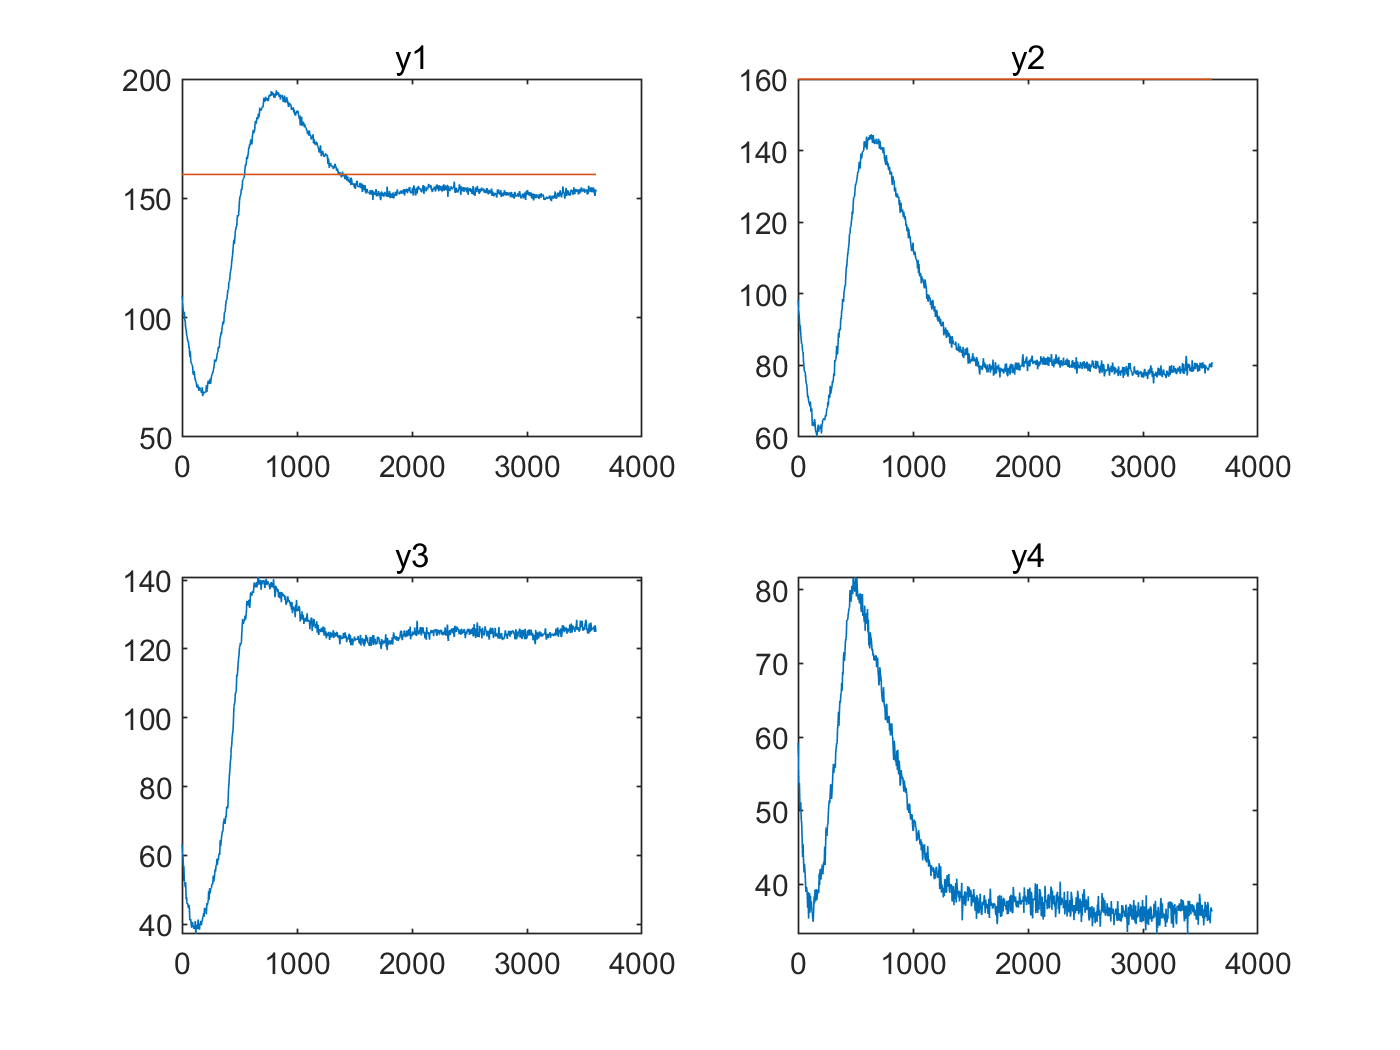

figure
subplot(2,2,1)
plot(t,y(1,:),t,(ref)*ones(size(t,1),1))
title('y1')
subplot(2,2,2)
plot(t,y(2,:),t,(ref)*ones(size(t,1),1))
title('y2')
subplot(2,2,3)
plot(t,y(3,:))
title('y3')
subplot(2,2,4)
plot(t,y(4,:))
title('y4')

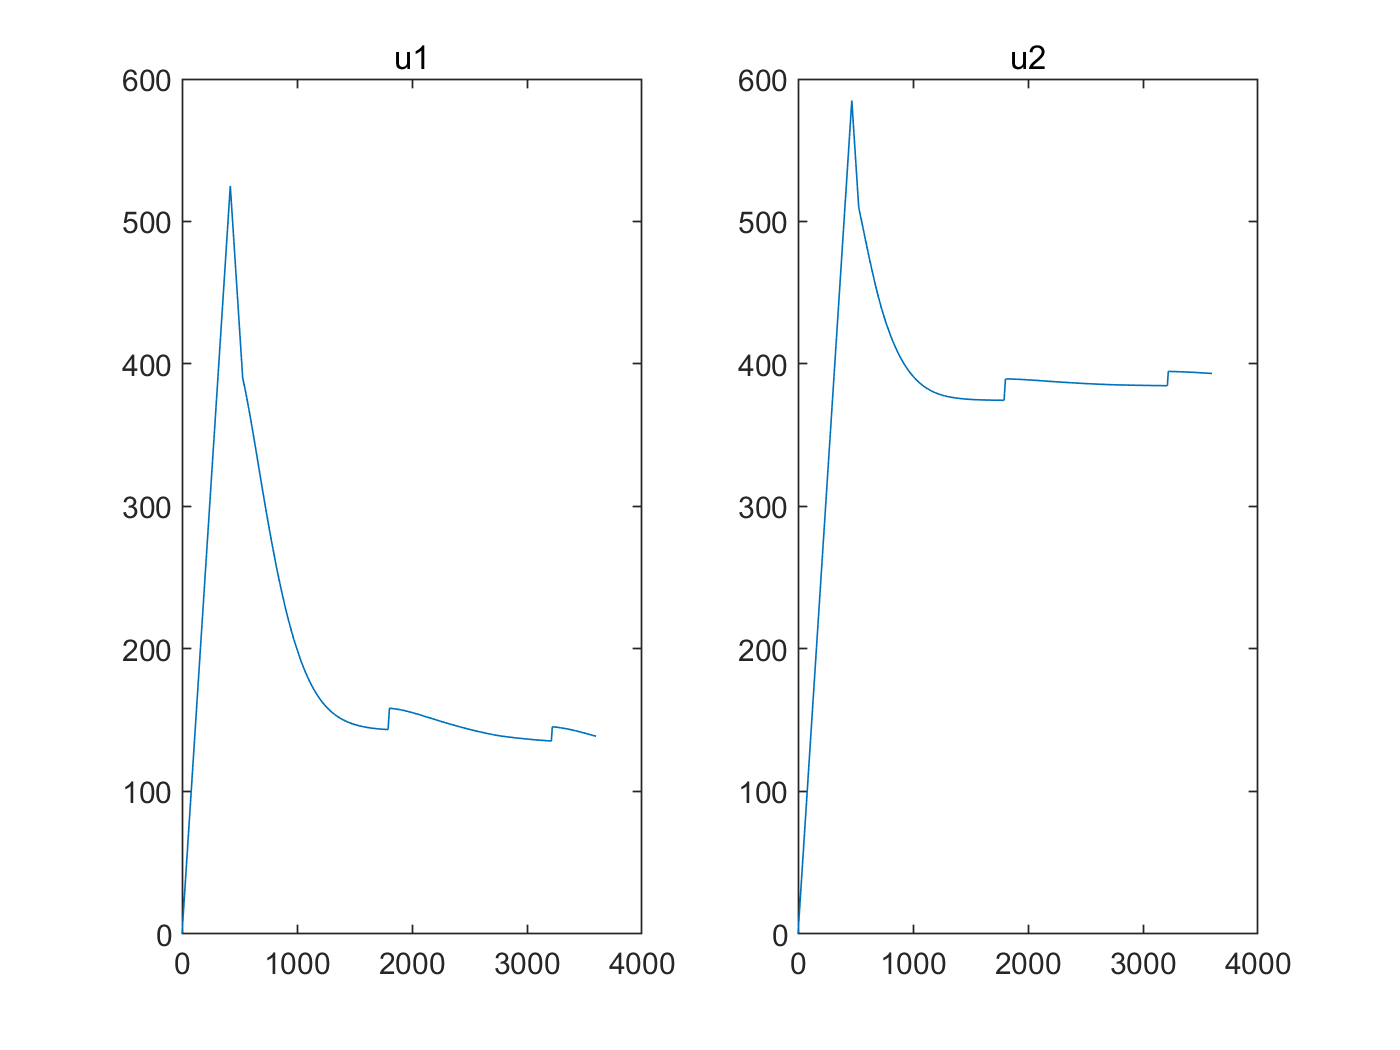

figure;
subplot(1,2,1)
plot(t,u(1,:))
title('u1')
subplot(1,2,2)
plot(t,u(2,:))
title('u2')

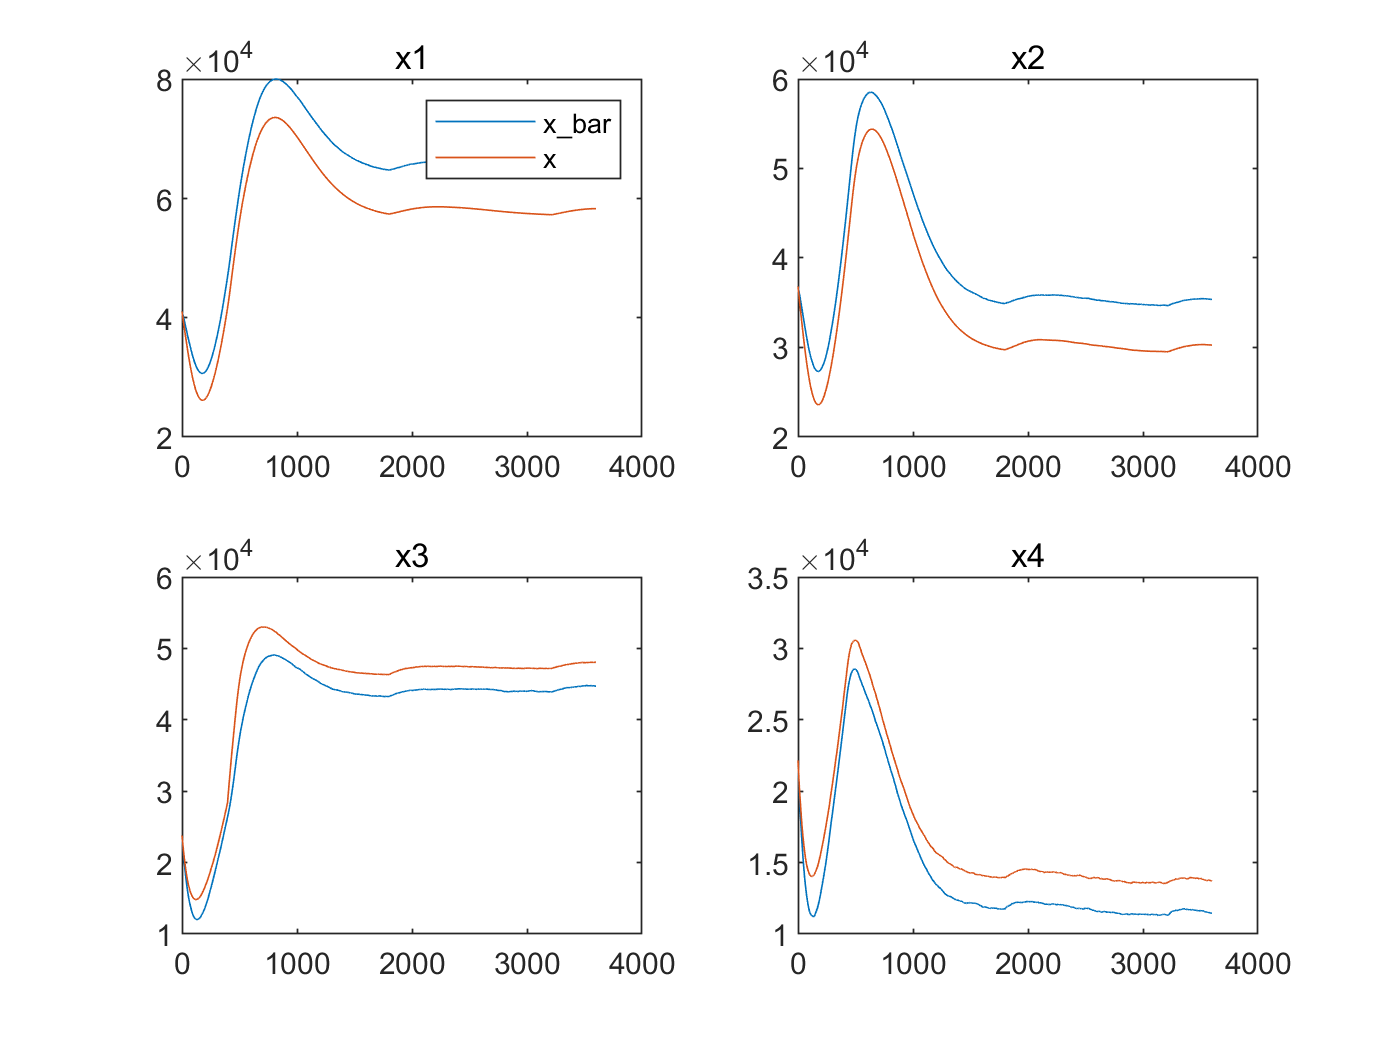

figure
subplot(2,2,1)
plot(t,x_bar(1,:),t,x(1,:))
title('x1')
legend('x\_bar','x')
subplot(2,2,2)
plot(t,x_bar(2,:),t,x(2,:))
title('x2')
subplot(2,2,3)
plot(t,x_bar(3,:),t,x(3,:))
title('x3')
subplot(2,2,4)
plot(t,x_bar(4,:),t,x(4,:))
title('x4')

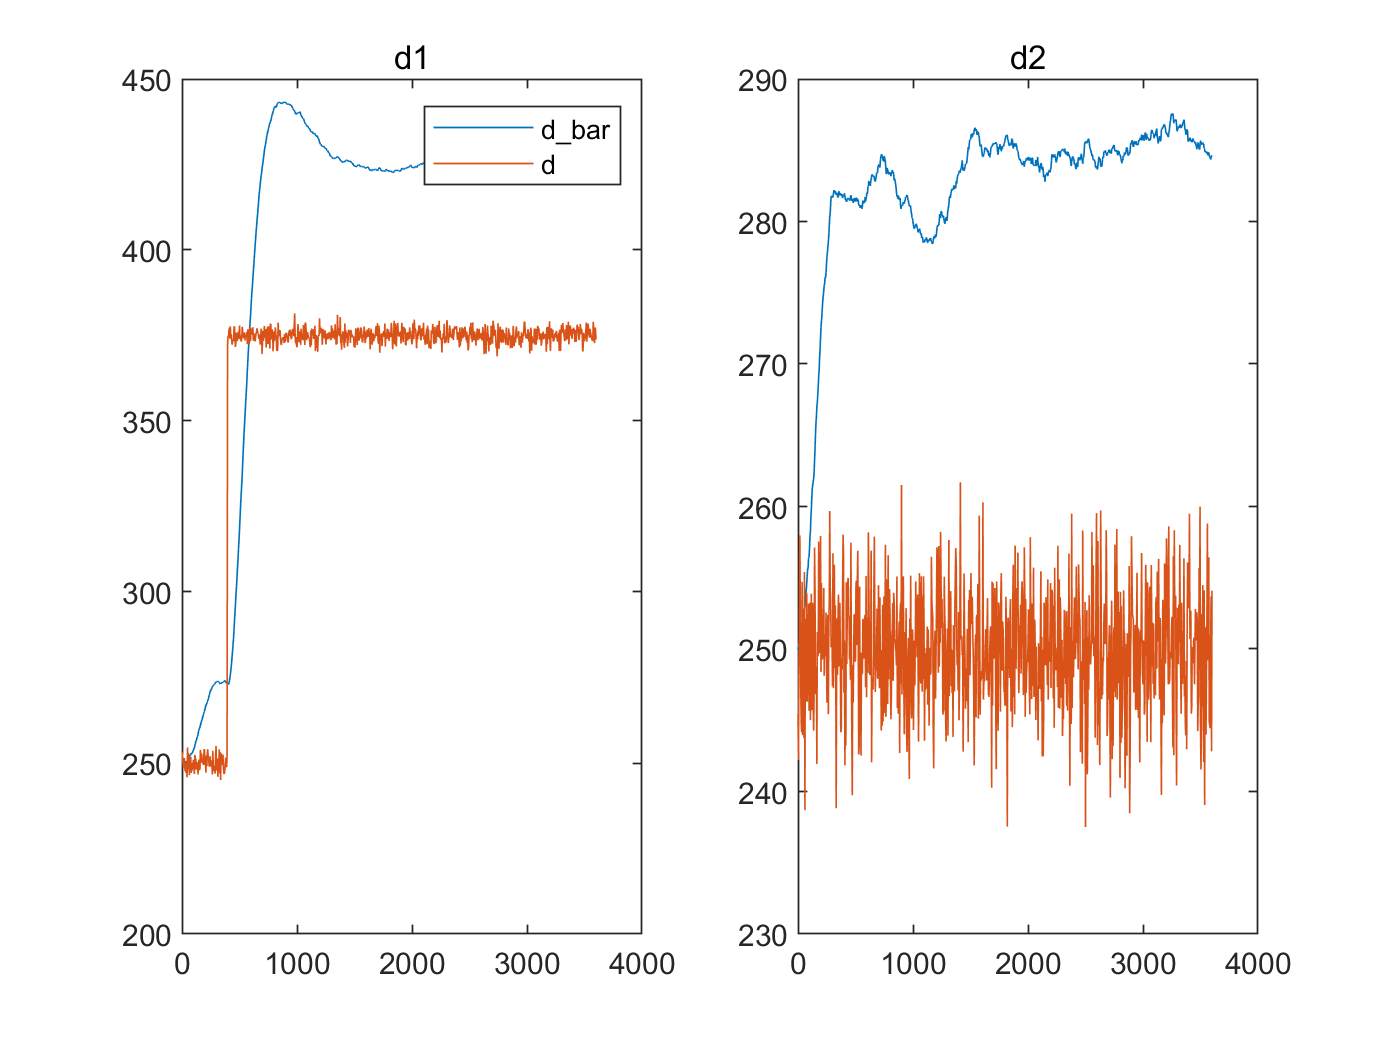

figure;
subplot(1,2,1)
plot(t,d_bar(1,:)+ds(1),t,dw(1,:));
title('d1')
legend('d\_bar','d')
subplot(1,2,2)
plot(t,d_bar(2,:)+ds(2),t,dw(2,:));
title('d2')

%测试线性系统下的PID效果
t0 = 0.0; % [s] Initial time
t_final = 20*60; % [s] Final time
Ts = 4; % [s] Sample Time (4s for the step)
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 250;
F4 = 250;
%x0 = [m10; m20; m30; m40];
x0=xs;
% Process Noise
Q = [0.5^2 0;0 0.5^2];
Lq = chol(Q,'lower');
w = Lq*randn(2,N);
% Measurement Noise
R_low = eye(4);
Lr_low = chol(R_low,'lower');
v_low = Lr_low*randn(4,N);
R_mid = 10*eye(4);
Lr_mid = chol(R_mid,'lower');
v_mid = Lr_mid*randn(4,N);
R_high = 20*eye(4);
Lr_high = chol(R_high,'lower');
v_high = Lr_high*randn(4,N);

index_step=100;
%step 0.05
u_50_F1 = [repmat(F1,1,N); repmat(F2,1,N)];
u_50_F2 = [repmat(F1,1,N); repmat(F2,1,N)];
u_50_F1(1,index_step:end)=F1*(1+0.5);
u_50_F2(2,index_step:end)=F2*(1+0.5);
%d = [repmat(F3,1,N); repmat(F4,1,N)];
d = [repmat(10,1,N); repmat(10,1,N)];
%d(1,index_step:end)=100*(1+0.5);
%step 0.1
u_10_F1 = [repmat(F1,1,N); repmat(F2,1,N)];
u_10_F2 = [repmat(F1,1,N); repmat(F2,1,N)];
u_10_F1(1,index_step:end)=F1*(1+0.1);
u_10_F2(2,index_step:end)=F2*(1+0.1);
%step 0.25
u_25_F1 = [repmat(F1,1,N); repmat(F2,1,N)];
u_25_F2 = [repmat(F1,1,N); repmat(F2,1,N)];
u_25_F1(1,index_step:end)=F1*(1+0.25);
u_25_F2(2,index_step:end)=F2*(1+0.25);
%impulse 0.1
u_impluse_F1=[repmat(F1,1,N); repmat(F2,1,N)];
u_impluse_F2=[repmat(F1,1,N); repmat(F2,1,N)];
u_impluse_F1(1,index_step)=F1*(1+0.1);
u_impluse_F2(2,index_step)=F2*(1+0.1);

dw=d+w;
num_x=4;
num_u=2;
num_d=2;
num_y=4;
num_z=2;
num_eta=num_y;

N_pre=10;
u_min=0;
u_max=600;
z_min=0;
z_max=131;
u_delta_min=-5;
u_delta_max=5;
x = zeros(num_x,N);
y = zeros(num_y,N);
z = zeros(num_z,N);
u = zeros(num_u,N);
x_bar = zeros(num_x,N);
d_bar = zeros(num_d,N);

x0=zeros(4,1);
d0=zeros(2,1);
x(:,1) = x0;
x_bar(:,1) = x0;
d_bar(:,1) = d0;
xk=x_bar(:,1);
ref=30;
%使用输出约束MPC时需要重构ref
rk=ref*ones(N_pre*num_z,1);%z1,z2 ref
%rk=ref*ones(N_pre*num_y,1);%y1,y2,y3,y4
%使用观测disturbance的第一个值时，需要重构d
%dk=[repmat(d_bar(1,1),N_pre,1); repmat(d_bar(2,1),N_pre,1)];%d1,d2 ref
dk=d_bar(:,1);
uk=zeros(num_u,1);%d1,d2 ref
usk=repmat(us(1),N_pre*num_u,1);
Q_cof=60;
u_delta_cof=100;%1000
eta_cof=1000;
Wu_cof=0.0001;

%PID
%如果不使用解耦矩阵，会发现pid会让u1为0，只控制u2来达到目的
%如果使用解耦矩阵，会发现pid会让u1,u2一起来控制
yk=Css*xk+Dss*uk+v_low(:,1); % Sensor function
yk_old=yk;
Ik=0;
KP=40;
KI=40;
KD=0;
decop=0.1*[-1.2000,1.3887;1.9010,-1.2000];
%decop=[1,0;0,1];
for k = 1:N-1
%sensor feedback
yk=Css*xk+Dss*uk+v_low(:,k); % Sensor function
yk_no_noise=Css*xk+Dss*uk;
zk=yk_no_noise(1:2,:); % Output function
y(:,k)=yk;
z(:,k)=zk;

%kalman observer
%static kalman
% x_kf=[x_bar(:,k);d_bar(:,k)];
% u_kf=uk;
% x_kf=Ad_kf*x_kf+Bd_kf*u_kf+L_kf*(yk-(Cdy_kf*x_kf+Dss*u_kf));
% xk = x_kf(1:num_x);
% %dk = [repmat(x_kf(num_x+1),N_pre,1); repmat(x_kf(num_x+2),N_pre,1)];
% dk=x_kf(num_x+1:num_x+2);

%dynamic kalman
% P = G_w*W_kf*G_w';
% x_kf=[x_bar(:,k);d_bar(:,k)];
% u_kf=u(:,k);
% y_bar=Cdy_kf*x_kf;
% e_bar=y(:,k)-y_bar;
% R=Cdy_kf*P*Cdy_kf'+R;
% K=P*Cdy_kf'*inv(R);
% x_kf=x_kf+K*e_bar;
% P=P-K*R*K';
% x_kf=Ad_kf*x_kf+Bd_kf*u_kf;
% P=Ad_kf*P*Ad_kf'+G_w*W_kf*G_w';
% %可以继续迭代求x
% %z_bar=Cz*x_kf;
% R=Cdy_kf*P*Cdy_kf';
% xk = x_kf(1:num_x);
% %dk = [repmat(X_bar(num_x+1),N_pre,1); repmat(X_bar(num_x+2),N_pre,1)];
% dk=x_kf(num_x+1:num_x+2);

%MPC controller assuming the disturbance of prediction time is all known
%uk=MPCcompute_linear(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre);
%uk=MPCcompute_linear_qp_analytical(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre,Q_cof,u_delta_cof);
%uk=MPCcompute_linear_qp_numerical(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre,Q_cof,u_delta_cof);
%uk=MPCcompute_linear_inputCons_qp_numerical(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,u_min,u_max,u_delta_min,u_delta_max,N_pre,Q_cof,u_delta_cof);
%uk=MPCcompute_linear_inputCons_outputSoftCons_qp_numerical(rk,xk,dk,uk,Ad,Bd,Bd_d,Css,u_min,u_max,u_delta_min,u_delta_max,z_min,z_max,N_pre,Q_cof,u_delta_cof,eta_cof);

%MPC controller only use the first disturbance
%uk=MPCcompute_linear_qp_analytical_kalman(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre,Q_cof,u_delta_cof);
%uk=MPCcompute_linear_qp_numerical_kalman(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre,Q_cof,u_delta_cof);
%uk=MPCcompute_linear_inputCons_qp_numerical_kalman(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,u_min,u_max,u_delta_min,u_delta_max,N_pre,Q_cof,u_delta_cof);
%uk=MPCcompute_linear_inputCons_outputSoftCons_qp_numerical_kalman(rk,xk,dk,uk,Ad,Bd,Bd_d,Css,u_min,u_max,u_delta_min,u_delta_max,z_min,z_max,N_pre,Q_cof,u_delta_cof,eta_cof);

%uk=MPCcompute_linear_kalman_target(rk,xk,dk,uk,usk,Ad,Bd,Bd_d,Czss,N_pre,Q_cof,u_delta_cof,Wu_cof);
%uk=MPCcompute_linear_inputCons_kalman_target(rk,xk,dk,uk,usk,Ad,Bd,Bd_d,Czss,u_min,u_max,u_delta_min,u_delta_max,N_pre,Q_cof,u_delta_cof,Wu_cof);


%PID controller
[uk,Ik] = MIMOPID(0,ref,yk(1:2),yk_old(1:2),Ik,KP,KI,KD,Ts,u_min,u_max,decop);
yk_old=yk;
%state update
xk=Ad*x(:,k)+Bd*uk+Bd_d*d(:,k)+Gw_d*w(:,k);


x(:,k+1)=xk;
u(:,k+1)=uk;
% x_bar(:,k+1) = x_kf(1:num_x);
% d_bar(:,k+1) = x_kf(num_x+1:end);
end
k=N;
yk=Css*x(:,k)+Dss*uk+v_low(:,k); % Sensor function
yk_no_noise=Css*xk+Dss*uk;
zk=yk_no_noise(1:2,:); % Output function
y(:,k)=yk;
z(:,k)=zk;

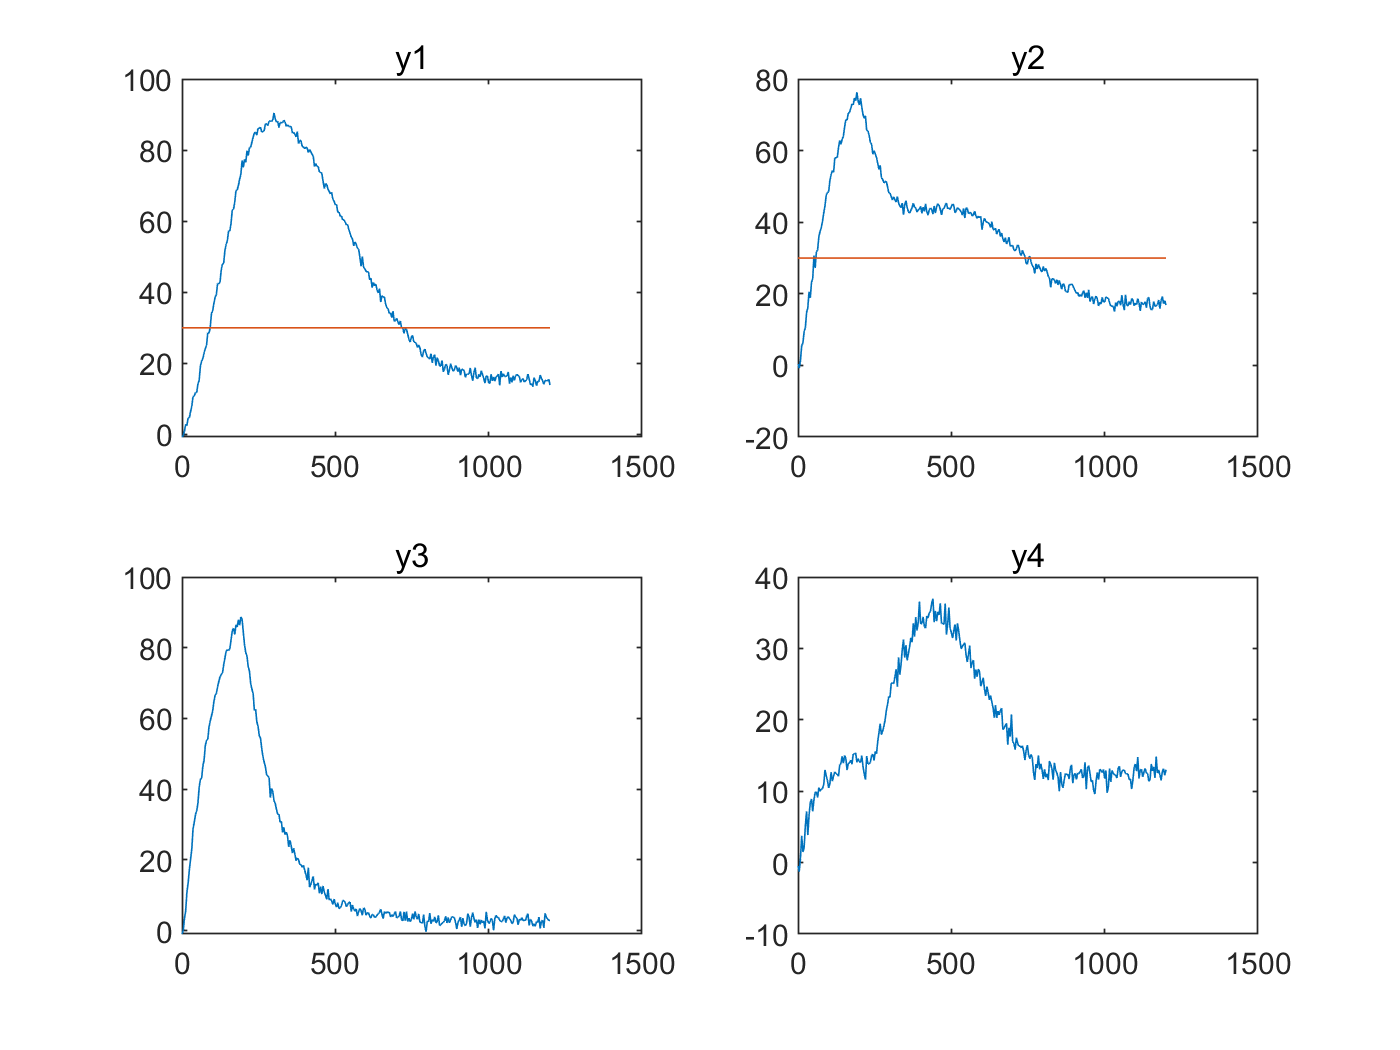

figure
subplot(2,2,1)
plot(t,y(1,:),t,(ref)*ones(size(t,1),1))
title('y1')
subplot(2,2,2)

plot(t,y(2,:),t,(ref)*ones(size(t,1),1))
title('y2')
subplot(2,2,3)
plot(t,y(3,:))
title('y3')
subplot(2,2,4)
plot(t,y(4,:))
title('y4')

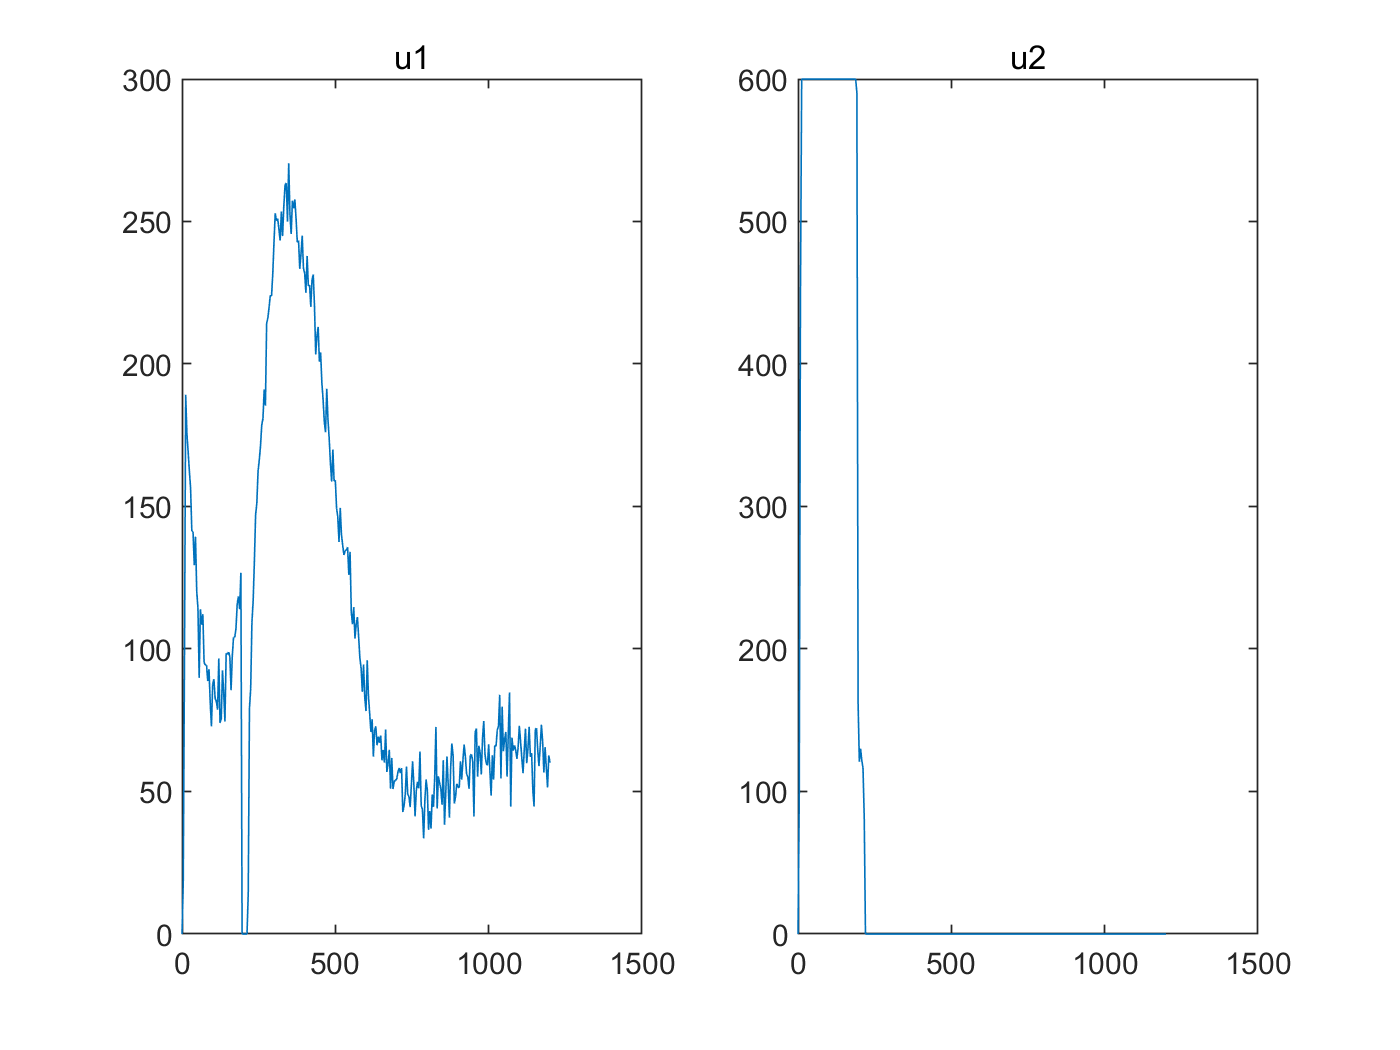

figure;
subplot(1,2,1)
plot(t,u(1,:))
title('u1')
subplot(1,2,2)
plot(t,u(2,:))
title('u2')

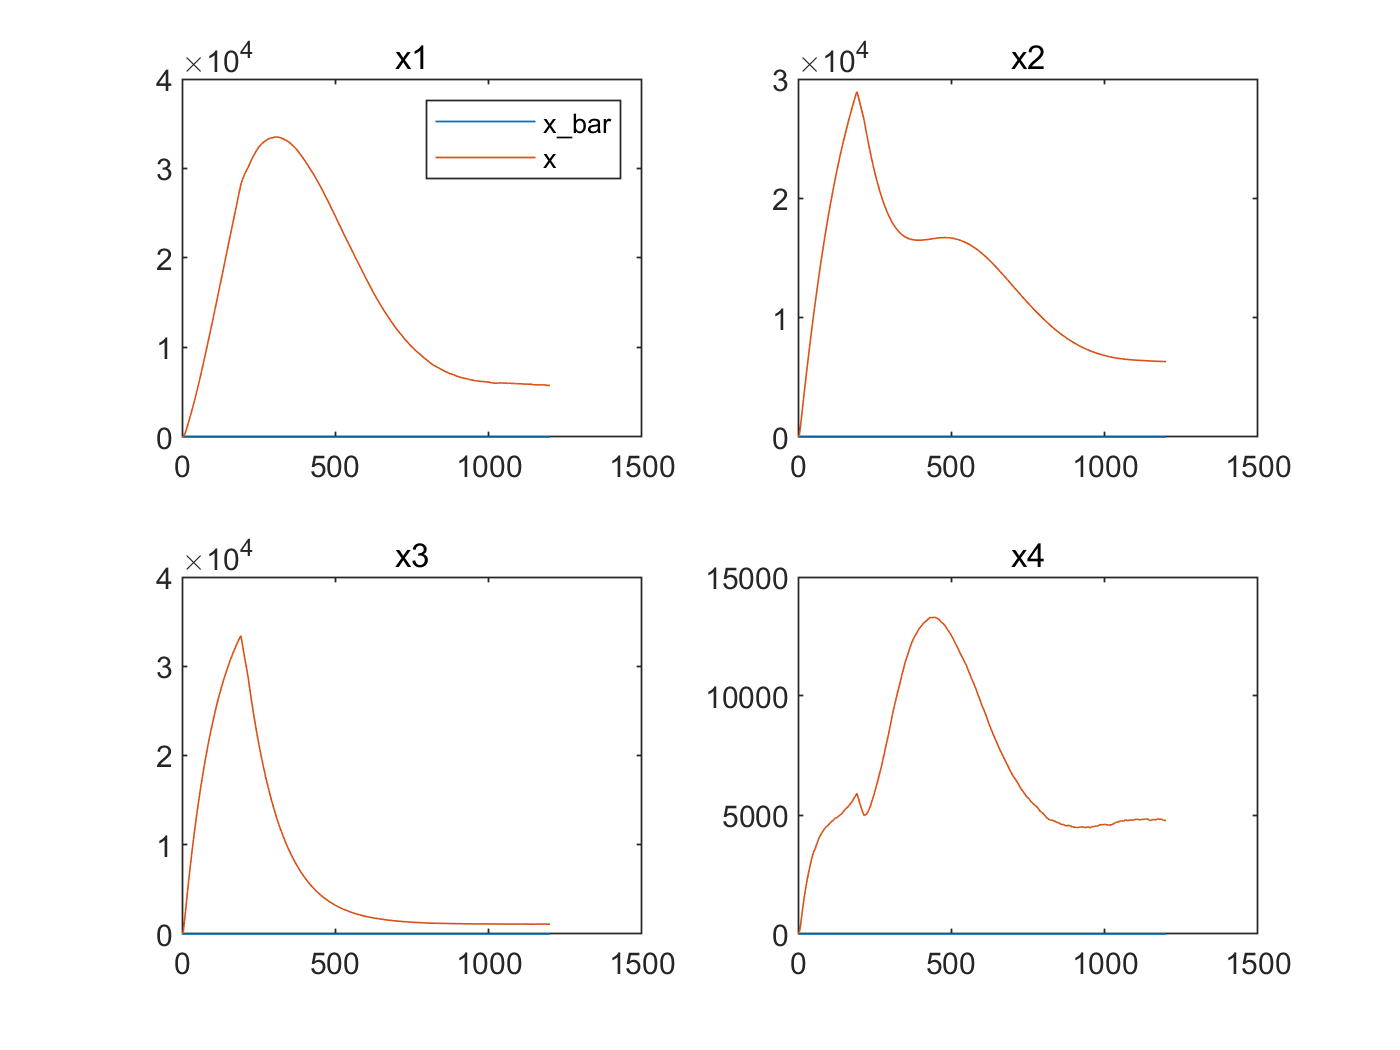

figure
subplot(2,2,1)
plot(t,x_bar(1,:),t,x(1,:))
title('x1')
legend('x\_bar','x')
subplot(2,2,2)
plot(t,x_bar(2,:),t,x(2,:))
title('x2')
subplot(2,2,3)
plot(t,x_bar(3,:),t,x(3,:))
title('x3')
subplot(2,2,4)
plot(t,x_bar(4,:),t,x(4,:))
title('x4')

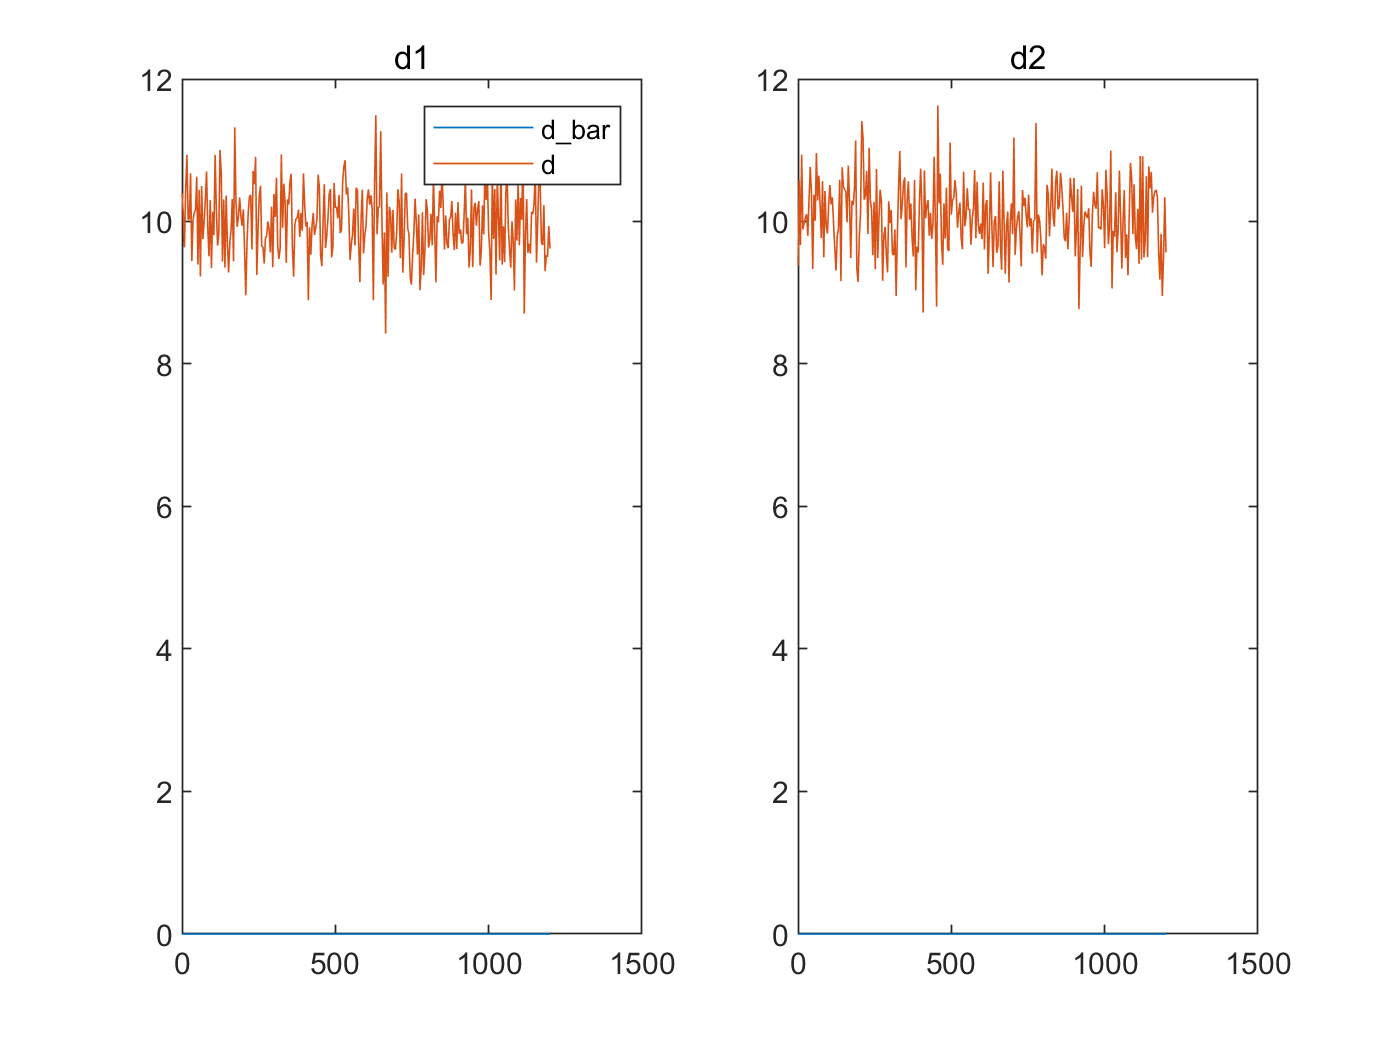

figure;
subplot(1,2,1)
plot(t,d_bar(1,:),t,dw(1,:));
title('d1')
legend('d\_bar','d')
subplot(1,2,2)
plot(t,d_bar(2,:),t,dw(2,:));
title('d2')